## Лабораторная №4

### Генетические алгоритмы

Выполнил: Топольницкий А.

Проверил: Маргун А.А.

clear all; close all; clc;

Задание интервала дискретизации, количества индивидуумов в популяции и число поколений. Задание передаточной функции

dt = 0.001;   % интервал дискретизации
PopSize = 30;
MaxGenerations = 15; 
s = tf('s');      % символическое задание оператора Лапласа
G = 1 / (s * (s * s + s + 1));    % передаточная функция объекта управления

Задание оптимальных значений параметров регулятора и вызов функции ga()

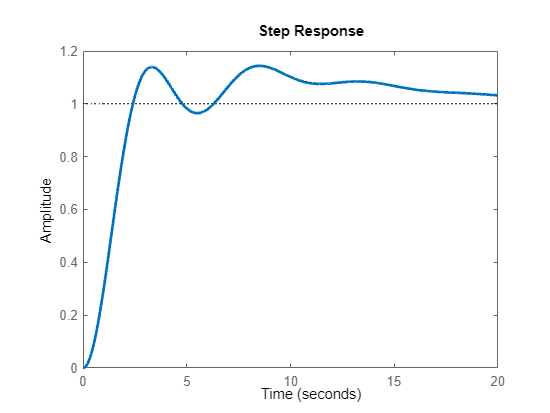

Optimization terminated: maximum number of generations exceeded.


options = optimoptions(@ga,'PopulationSize',PopSize,'MaxGenerations',MaxGenerations,'OutputFcn',@history_func);
[x,fval] = ga(@(K)PID_func(G,dt,K),3,-eye(3),zeros(3,1),[],[],[],[],[],options);

Построение необходимых графиков

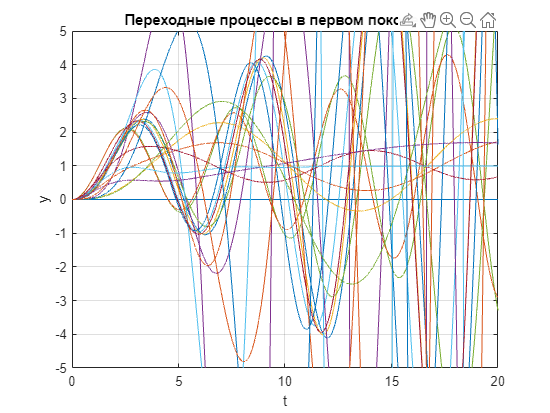

data = load('history.mat', 'cost', 'history');

figure()
for i = 1 : size(data.cost, 1)
    [y, u, t, ClosedLoop] = plotting(G,dt,data.history(i, :, 1));
    plot(t, y)
    ylim([-5 5])
    ylabel('y')
    xlabel('t')
    grid on
    title('Переходные процессы в первом поколении')
    hold on
end

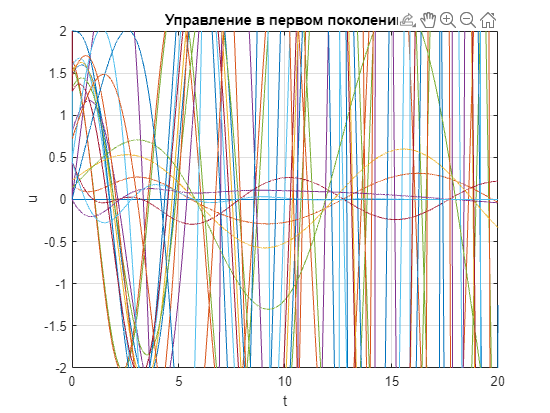

figure()
for i = 1 : size(data.cost, 1)
    [y, u, t, ClosedLoop] = plotting(G,dt,data.history(i, :, 1));
    plot(t, u)
    ylim([-2 2])
    ylabel('u')
    xlabel('t')
    grid on
    title('Управление в первом поколении')
    hold on
end

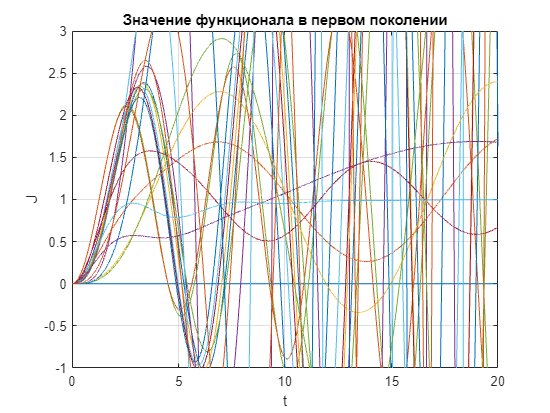

figure()
for i = 1 : size(data.cost, 1)
    [y, u, t, ClosedLoop] = plotting(G,dt,data.history(i, :, 1));
    plot(t, step(ClosedLoop,t))
    ylim([-1 3])
    ylabel('J')
    xlabel('t')
    grid on
    title('Значение функционала в первом поколении')
    hold on
end

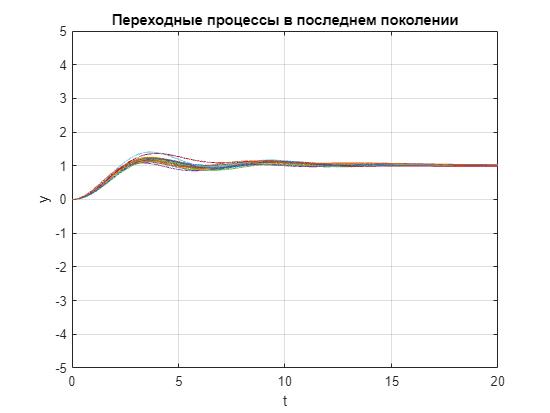

figure()
for i = 1 : size(data.cost, 1)
    [y, u, t, ClosedLoop] = plotting(G,dt,data.history(i, :, 16));
    plot(t, y)
    ylim([-5 5])
    ylabel('y')
    xlabel('t')
    grid on
    title('Переходные процессы в последнем поколении')
    hold on
end

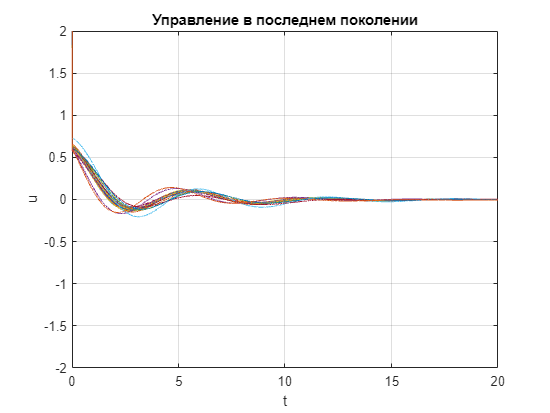

figure()
for i = 1 : size(data.cost, 1)
    [y, u, t, ClosedLoop] = plotting(G,dt,data.history(i, :, 16));
    plot(t, u)
    ylim([-2 2])
    ylabel('u')
    xlabel('t')
    grid on
    title('Управление в последнем поколении')
    hold on
end

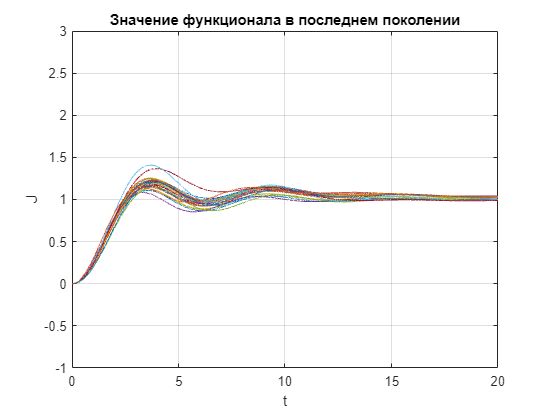

figure()
for i = 1 : size(data.cost, 1)
    [y, u, t, ClosedLoop] = plotting(G,dt,data.history(i, :, 16));
    plot(t, step(ClosedLoop,t))
    ylim([-1 3])
    ylabel('J')
    xlabel('t')
    grid on
    title('Значение функционала в последнем поколении')
    hold on
end

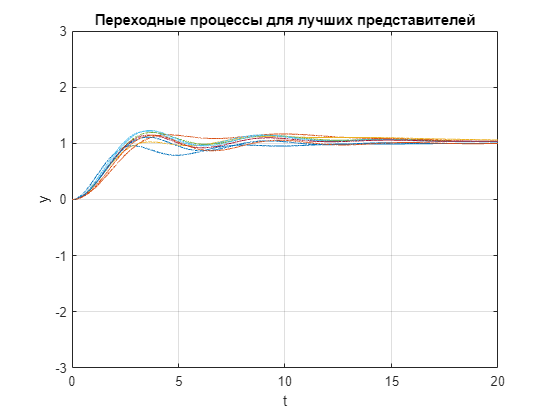

% массив индексов для определения лучших индивидуумов в каждом поколении
J_min_ind = zeros(1, size(data.cost, 2));
for i = 1 : size(data.cost, 2)
    J_min_ind(i) = min(find(data.cost(:, i) == min(data.cost(:, i))));
end

figure()
for i = 1 : size(data.cost, 2)
    [y, u, t, ClosedLoop] = plotting(G,dt,data.history(J_min_ind(i), :, i));
    plot(t, y)
    ylim([-3 3])
    ylabel('y')
    xlabel('t')
    grid on
    title('Переходные процессы для лучших представителей')
    hold on
end

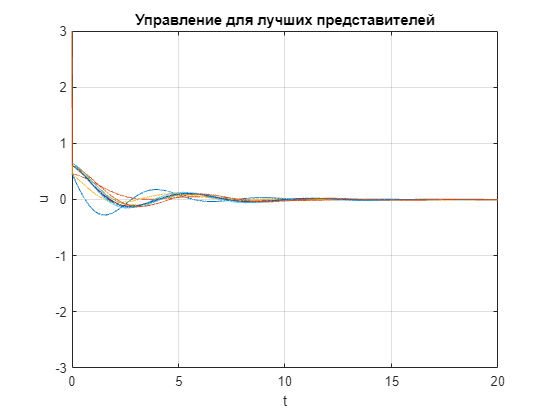


figure()
for i = 1 : size(data.cost, 2)
    [y, u, t, ClosedLoop] = plotting(G,dt,data.history(J_min_ind(i), :, i));
    plot(t, u)
    ylim([-3 3])
    ylabel('u')
    xlabel('t')
    grid on
    title('Управление для лучших представителей')
    hold on
end

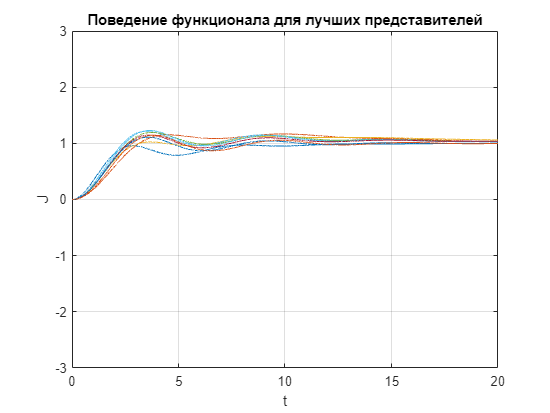


figure()
for i = 1 : size(data.cost, 2)
    [y, u, t, ClosedLoop] = plotting(G,dt,data.history(J_min_ind(i), :, i));
    plot(t, step(ClosedLoop,t))
    ylim([-3 3])
    ylabel('J')
    xlabel('t')
    grid on
    title('Поведение функционала для лучших представителей')
    hold on
end